poverty = [15.7; 8.4; 14.7; 17.3; 13.3; 11.4; 9.3; 10.0; 13.2; 14.7; 9.1; 12.6];
income = [42666; 68460; 50958; 38815; 61021; 56993; 68595; 57989; 47778; 50861; 67214; 47576];

poverty_adj = (poverty - mean(poverty)) / std(poverty);

poverty_adj =     1.1265
   -1.4233
    0.7772
    1.6853
    0.2882
   -0.3755
   -1.1090
   -0.8645
    0.2532
    0.7772


income_adj = (income - mean(income)) / std(income);

income_adj =    -1.2140
    1.3434
   -0.3919
   -1.5958
    0.6058
    0.2065
    1.3567
    0.3052
   -0.7071
   -0.4015


correlation = corr(poverty_adj, income_adj)

correlation = -0.9005

correlation = -9.9057

A = 1/sqrt(11) * [poverty_adj income_adj];
C = A' * A

C =     1.0000   -0.9005
   -0.9005    1.0000


C = corrcoef([poverty_adj income_adj])

C =     1.0000   -0.9005
   -0.9005    1.0000


clear
load('face_bases.mat')

im1 = test_images(:,:,1);
im2 = test_images(:,:,2);
im3 = test_images(:,:,3);

dist_im12 = sqrt(sum(sum(((im1-im2).^2))))

dist_im12 = 0.1565

dist_im23 = sqrt(sum(sum(((im2-im3).^2))))

dist_im23 = 0.1184

dist_im13 = sqrt(sum(sum(((im1-im3).^2))))

dist_im13 = 0.0797

faces = test_images(:,:,1:6);
dfaces = imresize(faces,[25 25]);
rdfaces = reshape(dfaces,size(dfaces,1) * size(dfaces,2),size(dfaces,3));
c = corrcoef(rdfaces)

c =     1.0000    0.8607    0.9713    0.9520    0.9048    0.8380
    0.8607    1.0000    0.9230    0.9497    0.8818    0.7530
    0.9713    0.9230    1.0000    0.9763    0.8958    0.7757
    0.9520    0.9497    0.9763    1.0000    0.9131    0.7809
    0.9048    0.8818    0.8958    0.9131    1.0000    0.9284
    0.8380    0.7530    0.7757    0.7809    0.9284    1.0000


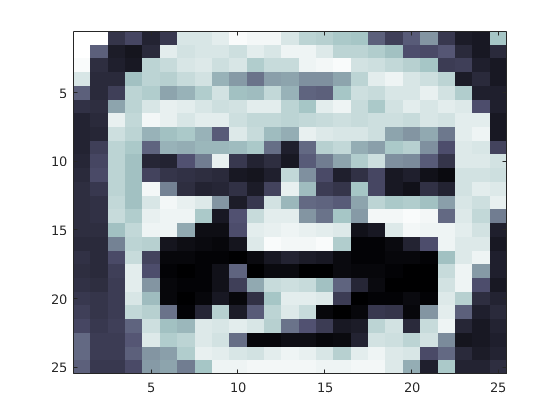

im_corr = corrcoef(transpose(rdfaces));
im_corr_adj = reshape(im_corr(:,1), 25, 25);
imagesc(im_corr_adj)
colormap(bone)